# Quantized Deep Neural Network on Jetson AGX Xavier Using GPU Coder

本例題では、物体(六角ナット)上の欠陥を検出するネットワークの構築、ネットワークの量子化と、コード生成によるJetson AGX Xavierへの実装の流れをご紹介します。必要なToolbox、3rd-party ツールがありますので、実行前に以下Prerequisitesをご覧ください。

This example demonstrates how to:

- Load and explore image data

- Define the network architecture and training options

- Train the network and classify validation images

- Quantize network to reduce memory footprint

- Walk through whole algorithm that consist of pre-processing, CNN and post-processing

- Generate CUDA C++ code(MEX) for whole algorithm

- Deploy algorithms to NVIDIA hardware

- Run the Executable on the Target

### Prerequisites - MathWorks Products and Support Packages

- MATLAB Coder™

- GPU Coder™

- Parallel Computing Toolbox™

- Deep Learning Toolbox™

- Image Processing Toolbox™

- Computer Vision Toolbox™

### Prerequisites - Development Host Requirements

- NVIDIA® GPU enabled for CUDA with compute capability 3.2 or higher (6.1 or higher is required for quantization)

- NVIDIA CUDA toolkit and driver

- C/C++ Compiler 

- CUDA Deep Neura Network library (cuDNN)

- Open Source Computer Vision Library v3.1.0 or higher for reading and displaying images/video

- (Optional) NVIDIA TensorRT

- The support package GPU Coder Interface for Deep Learning

- GPU Coder Support Package for NVIDIA GPUs

- The support package Deep Learning Toolbox Model Quantization Library. To install support packages, use the Add-On Explorer.

- Environment variables for the compilers and libraries. For information on the supported versions of the compilers and libraries, see [Third-party Products](https://jp.mathworks.com/help/gpucoder/gs/install-prerequisites.html). For setting up the environment variables, see [Setting Up the Prerequisite Products](https://jp.mathworks.com/help/gpucoder/gs/setting-up-the-toolchain.html).

### Prerequisites - Target Board Requirements

- NVIDIA Jetson AGX Xavier

- Ethernet crossover cable to connect the target board and host PC (if the target board cannot be connected to a local network)

- NVIDIA CUDA toolkit and driver

- CUDA Deep Neura Network library (cuDNN)

- Open Source Computer Vision Library v3.1.0 or higher for reading and displaying images/video

- Environment variables on the target for the compilers and libraries. For information on the supported versions of the compilers and libraries and their setup, see [installing and setting up prerequisites for NVIDIA boards](https://www.mathworks.com/help/supportpkg/nvidia/ug/install-and-setup-prerequisites.html).

clear; close all; imtool close all; clc;rng('default')

## 1. Load and explore image data

サンプルの画像データをimageDatastoreとして読み込みます。

categ = {'good', 'defective'};
imds = imageDatastore(fullfile(pwd, 'trainingImages', categ), 'IncludeSubfolders',1,'LabelSource', 'foldernames')

imds =   ImageDatastore のプロパティ:

                       Files: {
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame1.png';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame10.png';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good\frame100.png'
                               ... and 779 more
                              }
                     Folders: {
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\good';
                              ' ...\Demos\DeepLearning\H7_CAM\FEX\trainingImages\defective'
                              }
                      Labels: [good; good; good ... and 779 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
  

imds.ReadFcn = @(filename) readFunctionTrain(filename);
% Prepare data for TensorRT int8 calibration.
% Loaded image we have now is all gray scale image. Copy and stack gray scale image
% three times to replicate the 3 channels of RGB. We can do the same thing by
% assigning ReadFcn to imageDatastore instead, but we can't use datastore for TensorRT calibration and 
% need to prepare RGB data stored in the specific folder. 
prepareData4Calibration(imds)
countEachLabel(imds)

ans = 2×2 table
      Label      Count
    _________    _____

    defective     509 
    good          273 


### Display some of the images of defect product(hexagon nut) in the datastore

画像データを可視化します。ナットの表面に打痕やキズが確認できます。

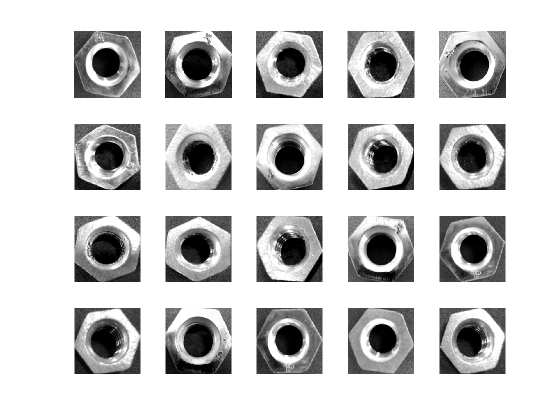

figure;
idx = find(imds.Labels == 'defective');
perm = randperm(size(idx,1),20);
for i = 1:20
    subplot(4,5,i);
    imshow(readimage(imds, idx(perm(i))));
end

### Specify Training and Validation Sets

データを学習用と検証用に分割します。90%を学習用データ、残りを検証用とします。

[trainingSet, validationSet] = splitEachLabel(imds, 0.9, 'randomize');

## 2. Define the Network Architecture and Training Options

ベースとなるネットワークとして、事前学習済のSqueezenetをロードします。このネットワークは1000クラスの一般物体(キーボード、マウス、動物等)を識別できるように学習されていますが、今回のナットの欠陥検出に利用するために、全結合層以降を置き換えます。

net = squeezenet;
inputSize = net.Layers(1).InputSize;

lgraph = layerGraph(net);
% Remove layers configured for 1000 classes
lgraph = removeLayers(lgraph, {'prob','ClassificationLayer_predictions'});
% Define new layers for 2 classes classification
newLayers = [...
    fullyConnectedLayer(2,'Name','fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    softmaxLayer('Name','prob')
    classificationLayer('Name','classoutput')];
% % Add new layers to layer graph
lgraph = addLayers(lgraph,newLayers);
% % Connect layers in layer graph
lgraph = connectLayers(lgraph,'pool10','fc');

### Data Augmentation

学習データの水増しを行います。ここでは画像を行方向、列方向に沿ってランダムに反転させる処理や、画像をランダムに回転させる処理が水増し用に追加されます。

augmenter = imageDataAugmenter('RandXReflection',true,'RandYReflection',true,...
    'RandRotation', [-180 180]);
datasource = augmentedImageSource(inputSize(1:2),trainingSet,'DataAugmentation',augmenter);

### Specify Training Options

学習オプションを指定します。InitialLearnRateを小さい値に設定し、Squeezenetから転移させた層の学習速度を下げます。新規に追加した層(全結合層)の学習率係数は10に設定されていますので、この学習率設定の組み合わせによって、新しい層では学習がより進むようになります。また、学習するエポック数の最大は15、ミニバッチのサイズは32とします。

options = trainingOptions('adam', ...
    'InitialLearnRate', 1e-4, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.7, ...
    'MaxEpochs', 15, ...
    'MiniBatchSize',32,...
    'ValidationData',validationSet, ...
    'ValidationFrequency',30, ...
    'ValidationPatience',Inf, ...
    'Plots','training-progress');

## 3. Train Network Using Training Data

学習データを使用してネットワークの学習を開始します。利用可能なGPUがある場合、trainNetworkはGPUを利用します。(Parallel Computing Toolbox™ とCompute Capability3.0以上のCUDA®対応GPUが必要です)　GPUが無い場合はCPUが使用されます。

学習時間はNVIDIA™ GeForce GTX 1070 使用時で1分程度です。

単一の GPU で学習中。
入力データの正規化を初期化しています。


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチの精度　　｜　　検証精度　　｜　　ミニバッチ損失　　｜　　検証損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　１　｜　　　　１　｜　　　　　００：００：０２　｜　　　　　３１．２５％　｜　６５．３８％　｜　　　１０．６９５９　｜　３．９１０８　｜　１．００００ｅ－０４　｜


｜　　　　　　２　｜　　　３０　｜　　　　　００：００：１２　｜　　　　　６８．７５％　｜　６６．６７％　｜　　　　０．６１９６　｜　０．５９９４　｜　１．００００ｅ－０４　｜


｜　　　　　　３　｜　　　５０　｜　　　　　００：００：１９　｜　　　　　６５．６３％　｜　　　　　　　　｜　　　　０．５６６４　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　　３　｜　　　６０　｜　　　　　００：００：２２　｜　　　　　５６．２５％　｜　６５．３８％　｜　　　　０．５７７９　｜　０．５３７９　｜　１．００００ｅ－０４　｜


｜　　　　　　５　｜　　　９０　｜　　　　　００：００：３２　｜　　　　　７１．８８％　｜　６９．２３％　｜　　　　０．４３０３　｜　０．４８２１　｜　１．００００ｅ－０４　｜


｜　　　　　　５　｜　　１００　｜　　　　　００：００：３５　｜　　　　　８１．２５％　｜　　　　　　　　｜　　　　０．３８４７　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　　６　｜　　１２０　｜　　　　　００：００：４２　｜　　　　　７５．００％　｜　７６．９２％　｜　　　　０．３９１７　｜　０．３５０６　｜　１．００００ｅ－０４　｜


｜　　　　　　７　｜　　１５０　｜　　　　　００：００：５２　｜　　　　　９３．７５％　｜　９４．８７％　｜　　　　０．１９９７　｜　０．１５１０　｜　１．００００ｅ－０４　｜


｜　　　　　　９　｜　　１８０　｜　　　　　００：０１：０２　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０１６２　｜　０．０４２７　｜　１．００００ｅ－０４　｜


｜　　　　　１０　｜　　２００　｜　　　　　００：０１：０９　｜　　　　　９６．８８％　｜　　　　　　　　｜　　　　０．０４７７　｜　　　　　　　　｜　１．００００ｅ－０４　｜


｜　　　　　１０　｜　　２１０　｜　　　　　００：０１：１２　｜　　　　１００．００％　｜　９７．４４％　｜　　　　０．０６３４　｜　０．０４５６　｜　１．００００ｅ－０４　｜


｜　　　　　１１　｜　　２４０　｜　　　　　００：０１：２２　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０３０１　｜　０．０４１０　｜　７．００００ｅ－０５　｜


｜　　　　　１２　｜　　２５０　｜　　　　　００：０１：２５　｜　　　　１００．００％　｜　　　　　　　　｜　　　　０．０３４３　｜　　　　　　　　｜　７．００００ｅ－０５　｜


｜　　　　　１３　｜　　２７０　｜　　　　　００：０１：３１　｜　　　　１００．００％　｜　９８．７２％　｜　　　　０．０３５６　｜　０．０２７６　｜　７．００００ｅ－０５　｜


｜　　　　　１４　｜　　３００　｜　　　　　００：０１：４０　｜　　　　　９６．８８％　｜　９８．７２％　｜　　　　０．０３８３　｜　０．０２６４　｜　７．００００ｅ－０５　｜


｜　　　　　１５　｜　　３３０　｜　　　　　００：０１：４９　｜　　　　　９６．８８％　｜　９８．７２％　｜　　　　０．０４０８　｜　０．０５６７　｜　７．００００ｅ－０５　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


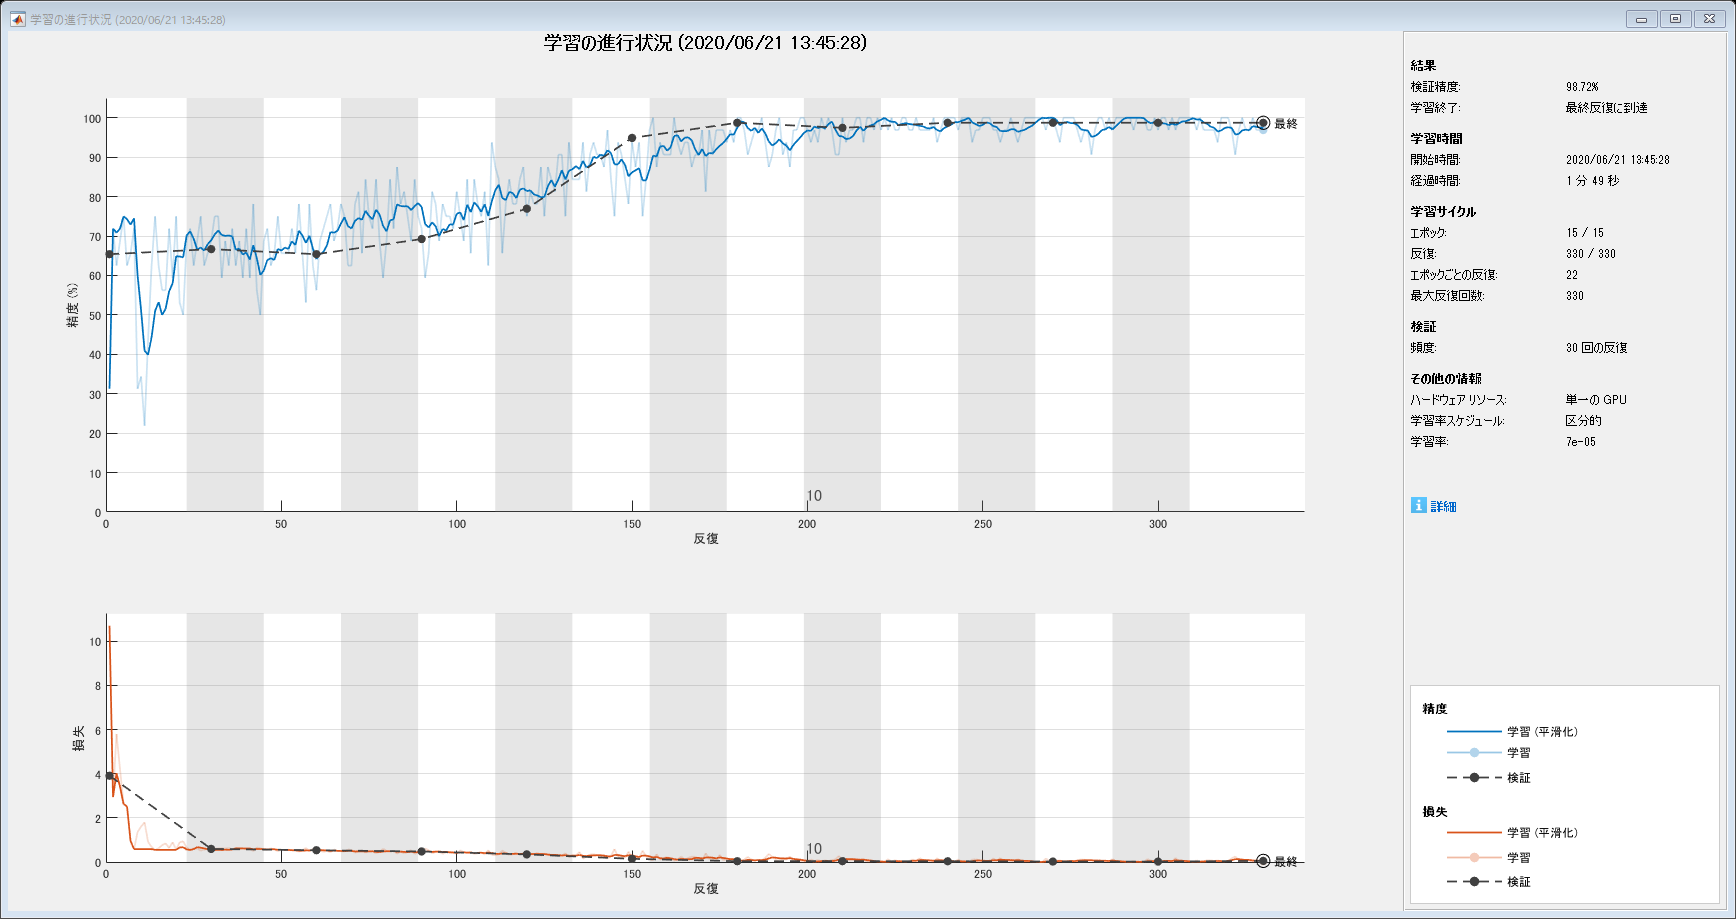

trainnet = true;
if trainnet
    convnet = trainNetwork(datasource,lgraph,options);
    save('mySqueezeNet.mat','convnet')
else
    % Load pre-trained network
    load('mySqueezeNet.mat')
end

### Classify Validation Images Using Trained Network

検証用に取り分けておいた画像を利用して分類精度を求めます。

predictedLabels = classify(convnet, validationSet);
valLabels = validationSet.Labels;

accuracy = sum(predictedLabels == valLabels)/numel(valLabels)

accuracy = 0.9872

1枚画像データを読み出し、分類結果とともに可視化します。

idx = 65;
[img, info] = readimage(validationSet, idx);
info.Label

ans = categorical
     defective 


[out, score] = classify(convnet, img)

out = categorical
     defective 


score = 1×2 の single 行ベクトル
    1.0000    0.0000


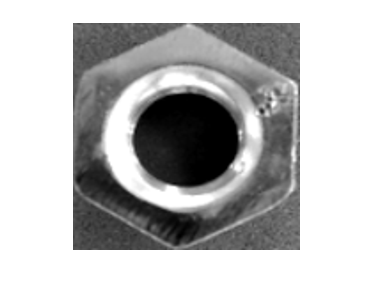

figure, imshow(img)

## 4. Quantize Network to Reduce Memory Footprint

ネットワークの量子化を行い、組み込み用にネットワークをコンパクトにします。ネットワークの量子化を行うためには、2つのサポートパッケージ(GPU Coder Interface for Deep Learning Libraries support package, Deep Learning Toolbox Model Quantization Library support package) が必要です。また、Compute Capability6.1以上のCUDA®対応GPUが必要となります。利用できる環境がない場合は量子化をスキップし、次のステップ(5. Walk through whole algorithm that consist of pre-processing, CNN and post-processing)に進んでください。ネットワークの量子化に関する詳細は、[Quantization of Deep Neural Networks](https://jp.mathworks.com/help/gpucoder/ug/quantization-of-deep-neural-networks.html)(GPU Coder)をご覧ください。

量子化を実行するのに必要なハードウェアが利用可能か確認します。

doCalib = false;
try 
    gpuInfo = gpuDevice;
    if gpuInfo.ComputeCapability > 6.0
        doCalib = true;
        disp('Network calibration can be run on this machine.')
    else
        disp(['GPU is available on this machine, but compute capability is ', gpuInfo.ComputeCapability, '.'])
    end
catch
    disp('Calibration process reuires CUDA Enabled GPU with compute capability 6.1 or higher.')
end

Network calibration can be run on this machine.


if doCalib

量子化のために、量子化用キャリブレーションデータと専用オブジェクトを準備します。

datasource_val = augmentedImageSource([227 227],validationSet,'DataAugmentation',augmenter);
% Create quantizer object
quantObj = dlquantizer(convnet);
% Specify the metric function in a dlquantizationOptions object
quantOpts = dlquantizationOptions('MetricFcn', ...
    {@(x)computeModelAccuracy(x, convnet, datasource_val)});

準備したデータを利用してキャリブレーションを実行します。

calResults = calibrate(quantObj, datasource)

calResults = 98×5 table
                   Optimized Layer Name                      Network Layer Name        Learnables / Activations    MinValue     MaxValue
    __________________________________________________    _________________________    ________________________    _________    ________

    {'conv1_relu_conv1_Weights'                      }    {'relu_conv1'           }           "Weights"             -0.91934     0.88411
    {'conv1_relu_conv1_Bias'                         }    {'relu_conv1'           }           "Bias"               -0.080732     0.26546
    {'fire2-squeeze1x1_fire2-relu_squeeze1x1_Weights'}    {'fire2-relu_squeeze1x1'}           "Weights"              -1.3791      1.2459
    {'fire2-squeeze1x1_fire2-relu_squeeze1x1_Bias'   }    {'fire2-relu_squeeze1x1'}           "Bias"                 -0.1171     0.24211
    {'fire2-expand1x1_fire2-relu_expand1x1_Weights'  }    {'fire2-relu_expand1x1' }           "Weights"              -0.7391     0.91082
    {'fire2-expa

### Quantize and simulate the network

量子化を実行し、結果を保存します。この例では、75%程度のメモリ削減が期待できます。

valResults = validate(quantObj, datasource_val, quantOpts);
valResults.MetricResults.Result

ans = 2×3 table
    NetworkImplementation    MetricOutput    LearnableParameterMemory(bytes)
    _____________________    ____________    _______________________________

     {'Floating-Point'}        0.97436                   4.95e+06           
     {'Quantized'     }        0.98718                 1.2554e+06           


Save Quantizer Object

save('dlquantObj.mat', 'quantObj');

end

## 5. Walk through whole algorithm that consist of pre-processing, CNN and post-processing

カメラから取得した画像を読み込みます。ネットワークの学習に利用した画像はあらかじめ前処理が施されており、ナット部分にROIが限定されていましたが、実際は周辺の背景も含めて以下のような画像が入力として与えられます。

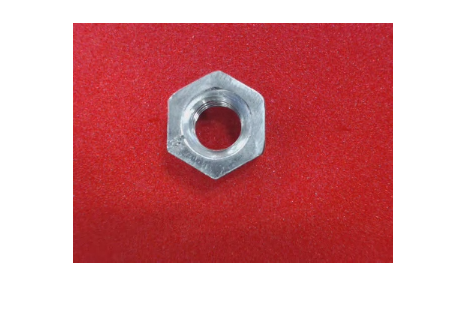

img = imread('images/defective.png');
figure, imshow(img)

ネットワークに入力する前に、予めナット部分をROIとして抽出する必要があります。

### Pre-processing for captured image from webCam

myNDNet_Preprocess関数を利用して前処理を施します。この関数では比較的計算コストの軽い画像処理によってナット部分をROIとして抽出します。また、最終的にコード生成を行ってメイン関数(main.cpp)と統合しますが、メイン関数ではOpenCVを利用して画像データをキャプチャしているため、フォーマットを合わせるために関数mat2ocvを利用してフォーマット変換をします。

wi = uint32(320);
he = uint32(240);
ch = uint32(3);

imgOcv = mat2ocv(img);
[Iori, nuts, num, bbox] = myNDNet_Preprocess(imgOcv);

### Display pre-processed image(extracted nuts)

前処理を行った結果を可視化してみます。ナット部分が抽出できていることを確認できます。

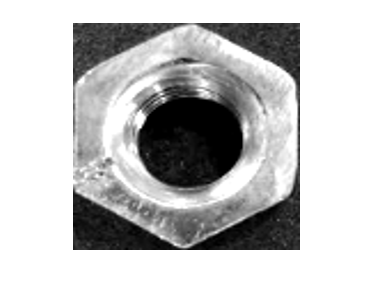

figure,
for i = 1:num
    subplot(1,num,i)
    imshow(nuts(:,:,i))
end

### Classify detected nuts by using pretrained network

前処理によってナット部分が抽出できましたが、この画像に対して学習済ネットワークが正しく分類を行えるかを確認してみます。また、同時にCAM(Class Activation Map)を利用して、最終的なスコアが画像データに依存していた場所を可視化させてみます。

Weights = convnet.Layers(67).Weights;
scores = zeros(2,4);
HeatMap = zeros(227,227,3,4);
for i = 1:num
    indata = repmat(nuts(:,:,i), [1 1 3]);
    scores(:,i) = convnet.predict(indata);
    act = convnet.activations(indata,'relu_conv10','OutputAs','channels');
    HeatMap(:,:,:,i) = CAMheatmap_squeezenet(indata,act,scores(:,i),Weights);
end
scores

scores =     1.0000         0         0         0
    0.0000         0         0         0


### Insert the labels in an image as an post-processing

分類結果をラベルとして画像に挿入します。また、CAMをヒートマップとして可視化します。

out = myNDNet_Postprocess(Iori, num, bbox, scores, wi, he, ch, HeatMap);

### Display post-processed image

結果を可視化します。ナットの傷がある部分に強く反応していることが確認できます。

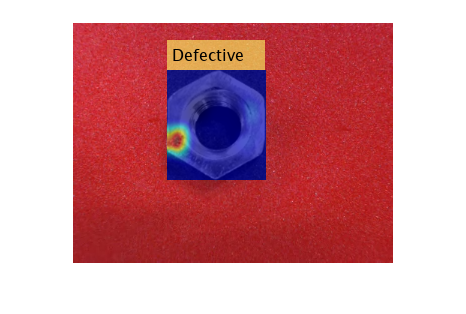

sz = [he wi ch];
out = ocv2mat(out,sz);

figure, imshow(out)

### Merge pre/post processing and prediction into a function for code generation

前処理/後処理とネットワークによる推論部分を一つの関数(targetFunction.m)にまとめます。また、実際に実行してこれまでと同様の結果が得られるか確認します。画像出力はOpenCVフォーマットになっているので、ocv2matにより変換を行ってから可視化します。

out2 = targetFunction(imgOcv,Weights,true);

out2 = ocv2mat(out2,sz);
figure, imshow(out2)

## 6. Generate CUDA C++ code(MEX) for 'targetFunction'

targetFunction.mに対してコード生成(MEX)を行い、MATLAB上で動作を確認します。coder.DeepLearningConfigを利用してコード生成に利用するライブラリを指定します。TensorRTを利用したコード生成も可能ですが、ここではcuDNNを選択します。GPU Coderを利用したコード生成の概要やチュートリアルは[GPU Coderの製品ページ](https://www.mathworks.com/products/gpu-coder)にて確認することができます。

% Select Library for Deep Neural Network
useTensorRT = 0; % 0:cuDNN(int8), 1:TensorRT(fp32), 2:TensorRT(int8) 

cfg = coder.gpuConfig('mex');
cfg.TargetLang = 'C++';

% Check compute capability of GPU
gpuInfo = gpuDevice;
cc = gpuInfo.ComputeCapability;

% Create deep learning code generation configuration object
switch useTensorRT
    case 0
        cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
        if doCalib
            cfg.DeepLearningConfig.CalibrationResultFile = fullfile(pwd,'dlquantObj.mat');
            cfg.DeepLearningConfig.DataType = 'int8';
        end
    case 1
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        cfg.GpuConfig.ComputeCapability = cc;
        cfg.DeepLearningConfig.DataType = 'fp32';        
    otherwise
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        % INT8 precision requires a CUDA GPU with minimum compute capability of
        % 6.1, except 6.2
        cfg.GpuConfig.ComputeCapability = cc;
        cfg.DeepLearningConfig.DataType = 'int8';
        cfg.DeepLearningConfig.DataPath = 'calibImages';
end

codegen -config cfg targetFunction -args {ones(240, 320, 3,'uint8'), coder.Constant(Weights), coder.Constant(true)} -report

コードの生成が成功しました:レポートの表示


### Run Generated MEX on the host machine

生成されたMEXが動作するか確認します。得られる結果がコード生成元となったtargetFunction.mと差分のないこと、エラーが出ていないことを確認します。

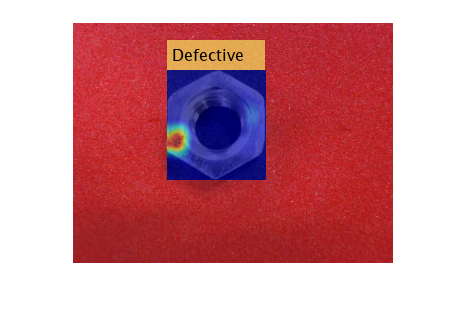

out = targetFunction_mex(imgOcv,Weights,true);
out = ocv2mat(out,sz);
figure, imshow(out)

## 7. Deploy algorithms to NVIDIA hardware

ここまでの作業で、画像の前処理/後処理とネットワークの推論部分を統合したtargetFunction.mが期待した通りに動作すること、生成したコードがホスト上で動作することを確認できました。次に、実際にJetson AGX Xavierにこのアルゴリズムを実装してみます。サポートパッケージ(GPU Coder support package for NVIDIA GPUs)を利用すると、ホストMATLABとターゲットハードウェアをネットワーク経由で接続でき、リモートビルド等が実行できるようになるので、非常に便利です。この例でもこのサポートパッケージを利用します。サポートパッケージの詳細については、[Getting Started with the GPU Coder Support Package for NVIDIA GPUs](https://www.mathworks.com/help/gpucoder/examples/getting-started-with-the-gpu-coder-support-package-for-nvidia-gpus.html) をご確認ください。

### Connect to the NVIDIA Hardware

サポートパッケージ(GPU Coder support package for NVIDIA GPUs)はTCP/IPを経由したSSH接続を利用してNVIDIA Jetson/Driveプラットフォーム上で各種コマンドの実行を可能にします。ターゲットハードウェアをホストマシンが接続されている同一ネットワークに接続するか、ホストマシンとハードウェアを直接Ethernetケーブルで接続し、以下コマンドを発行します。ターゲットハードウェアにログインするためのホスト名もしくはIPアドレス、ユーザー名とパスワードを予め把握している必要があります。

% You must know the host name or IP address, username, and password of the target board
hwobj = jetson('192.168.0.102', 'nvidia', 'nvidia')

Checking for CUDA availability on the Target...
Checking for 'nvcc' in the target system path...
Checking for cuDNN library availability on the Target...
Checking for TensorRT library availability on the Target...
Checking for prerequisite libraries is complete.
Gathering hardware details...
Checking for third-party library availability on the Target...
Gathering hardware details is complete.
 Board name         : NVIDIA Jetson AGX Xavier
 CUDA Version       : 10.0
 cuDNN Version      : 7.3
 TensorRT Version   : 5.0
 GStreamer Version  : 1.14.1
 V4L2 Version       : 1.14.2-1
 SDL Version        : 1.2
 Available Webcams  :  
 Available GPUs     : Xavier


hwobj =   jetson のプロパティ:

       DeviceAddress: '192.168.0.102'
                Port: 22
           BoardName: 'NVIDIA Jetson AGX Xavier'
         CUDAVersion: '10.0'
        cuDNNVersion: '7.3'
     TensorRTVersion: '5.0'
          SDLVersion: '1.2'
         V4L2Version: '1.14.2-1'
    GStreamerVersion: '1.14.1'
             GPUInfo: [1×1 struct]
          WebcamList: []


### Verify the GPU Environment

coder.checkGpuInstall 関数を利用して、コンパイラやライブラリ群がターゲット上で利用可能になっているか確認します。

envCfg = coder.gpuEnvConfig('jetson');
envCfg.BasicCodeexec = 1;
envCfg.DeepLibTarget = 'cudnn';
envCfg.DeepCodeexec = 1;
envCfg.HardwareObject = hwobj;
coder.checkGpuInstall(envCfg)

互換性のある GPU               : パス 
CUDA 環境                  : パス 
	ランタイム     : パス 
	cuFFT     : パス 
	cuSOLVER  : パス 
	cuBLAS    : パス 
cuDNN 環境                 : パス (警告: 深層学習コード生成は、cuDNN v7.5 を使用してテストされました。指定された cuDNN ライブラリの v7.3 に完全な互換性がない可能性があります。)
基本的なコードの生成               : パス 
基本的なコードの実行               : パス 
深層学習 (cuDNN) コードの生成      : パス 
深層学習 (cuDNN) コードの実行      : パス 


ans = フィールドをもつ struct :
                 gpu: 1
                cuda: 1
               cudnn: 1
            tensorrt: 0
        basiccodegen: 1
       basiccodeexec: 1
         deepcodegen: 1
        deepcodeexec: 1
    tensorrtdatatype: 0
           profiling: 0


### Generate CUDA Code for the Target Using GPU Coder

NVIDIAターゲットハードウェアに展開可能なCUDA実行可能ファイルを生成するために、GPUコードコンフィグレーションオブジェクトを作成します。

cfg = coder.gpuConfig('exe');
cfg.TargetLang = 'C++';
% Use the coder.hardware function to create a configuration object for the Jetson platform
% and assign it to the Hardware property of the code configuration object cfg.
cfg.Hardware = coder.hardware('NVIDIA Jetson');
cfg.Hardware.BuildDir = '~/remoteBuildDir';
cfg.CustomSource  = fullfile('main_nutsCam.cpp');

% Select Library for Deep Neural Network
useTensorRT = 0; % 0:cuDNN(int8), 1:TensorRT(fp32), 2:TensorRT(int8) 
% Create deep learning code generation configuration object
switch useTensorRT
    case 0
        cfg.DeepLearningConfig = coder.DeepLearningConfig('cudnn');
        if doCalib % Calibration 
            cfg.DeepLearningConfig.CalibrationResultFile = 'dlquantObj.mat';
            cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
            cfg.DeepLearningConfig.DataType = 'int8';
        end        
    case 1
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
        cfg.DeepLearningConfig.DataType = 'fp32';        
    otherwise
        cfg.DeepLearningConfig = coder.DeepLearningConfig('tensorrt');
        % INT8 precision requires a CUDA GPU with minimum compute capability of
        % 6.1, except 6.2
        cfg.GpuConfig.ComputeCapability = '7.2'; % Jetson Xavier
        cfg.DeepLearningConfig.DataType = 'int8';
        cfg.DeepLearningConfig.DataPath = 'calibImages';
end

codegen関数を利用してCUDAコードを生成します。ホスト上でコード生成が行われた後、生成されたファイルがターゲットにコピーされてビルドされます。

codegen -config cfg targetFunction -args {ones(240,320,3,'uint8'),coder.Constant(Weights),coder.Constant(false)} -report

コードの生成が成功しました:レポートの表示


## 8. Run the Executable on the Target

putFileメソッドを利用し、テスト用の入力画像をターゲットハードウェアにコピーします。

putFile(hwobj, 'images/defective.png', hwobj.workspaceDir);

### Launch the executable on the target hardware

runExecutableメソッドを利用して、ターゲットハードウェア上で実行可能ファイルを起動します。

exe = [hwobj.workspaceDir '/targetFunction.elf'];
useWebcam = false;
if ~useWebcam
    pid = hwobj.runExecutable(exe, ' 3 defective.png'); % Provide the input image;
else
    % Or if you have webCam connected to Jetson, you can use captured
    % image from webCam instead.
    pid = hwobj.runExecutable(exe, ' 1 0'); % "0" is deviceID for webCam
end

### Launching the executable on the target...
Executable launched successfully with process ID 13674.
Displaying the simple runtime log for the executable...

Note: For the complete log, run the following command in the MATLAB command window:
system(hwobj,'cat /home/nvidia/remoteBuildDir/MATLAB_ws/R2020a/C/Users/keitaro/OneDrive_-_MathWorks/Demos/DeepLearning/H7_CAM/FEX/targetFunction.log')


### Transfer file from target hardware to host computer

入力画像に対する出力結果はoutput.pngファイルとしてターゲットハードウェア上に保存されています。getFileメソッドを利用してホストマシンにこのファイルを転送します。テスト用の入力画像を利用せず、webCamを入力として利用している場合は、ターゲットハードウェアにモニタを接続して結果を確認します。

if ~useWebcam
    imgData = [hwobj.workspaceDir '/output.png'];
    getFile(hwobj, imgData)
end

### Display output image transfered from target hardware

ホストマシンに転送した画像を可視化し、結果を確認します

if ~useWebcam
    img = imread('output.png');
    figure, imshow(img)
else
    % You can kill the running executable on the target from the MATLAB environment on the host 
    % by using the killProcess() method of the hardware object.
    killProcess(hwobj, pid);
end

## Supporting Function

function I = readFunctionTrain(filename)
% Resize images to the size required by the network.
I = imread(filename);

if ismatrix(I)
    I = cat(3,I,I,I);
end
I = imresize(I, [227 227]);
end

*Copyright 2020 The MathWorks, Inc.*